% chenzhe, 2019-10-17. I think there is a better way to do this kind of
% summary.  So this code should be considered as historical.
clear;
addChenFunction;

dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('D:\p\m\DIC_Analysis\setting_for_real_samples\WE43_T6_C1_setting.mat','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');
[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis']);
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted']);
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

%% [data] strain data. Convert into v7.3 for partial loading
%%
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

%% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).
clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []                                         %iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');
trueTwinFile = matfile(fullfile(confirmedLabelPath,confirmedLabelFile));

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));



**(3) Now, something interesting.  We categorize the grain boundary into different groups, and look at how twinning activity is affected by the neighboring grains at these grain boundaries.  **

for iE = 2:5
    % For each grain, summarize a [b#,g#] pair for distMap purpose, for each twin activity.
    % Also, generate one data point from the mantle, contribution to one of the previous defined regions.
    
    NN = 250;
    x_dist = (1:NN)';
    qs_target = [0.0014, 0.0227, 0.1587, 0.5, 0.8414, 0.9772, 0.9987];
    mm = 0;
    MM = 150;
    % The analysis takes time, but we may directly load some results.
    try
        load(['temp_results/quants_wrt_gb_',num2str(iE),'.mat']);
    catch
        error("cannot load");
    end
    
    %% can plot distance map to illustrate
    if 0
        myplot(distMap_not_involved,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_co_found,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_twin_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_twin_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_growth_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_growth_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_co_growth,boundaryTFB + logical(trueTwinMapCell{iE}));
    end
end

**The effect of high strain on twin growth/activation:**

**For each grain and grain boundary, we calculate the ****mean ****of the effective strain of all data points at the same distance (d) to the grain boundary, for all distances d=1,2,3,...,250**

**and then for each category, we take all the grain and grain boundaries, and take the ****mean**** of all the mean effective strains @ each distances to grain boundary **

**So, we get a curve that represents the strain distribution w.r.t to distance to gb, for each category**

**--> If we have slip on one side of gb, and twinning on the otherside.  At the previous strain level, slip side strain was highest.**

**--> slip-slip, and slip side of slip-new twin pair, also tend to have high strain.**

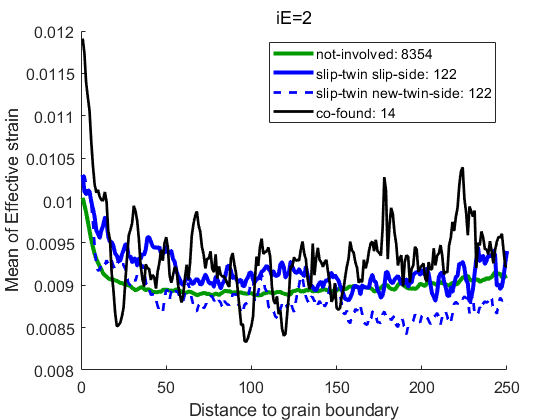

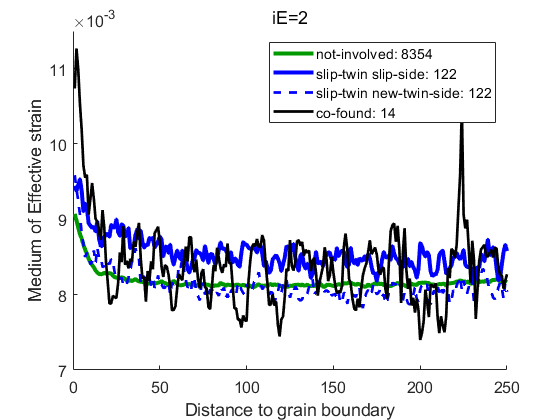

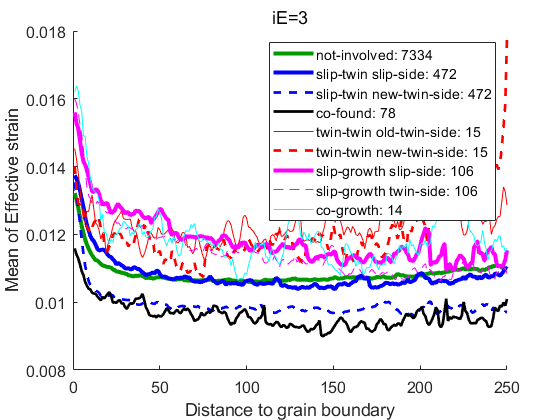

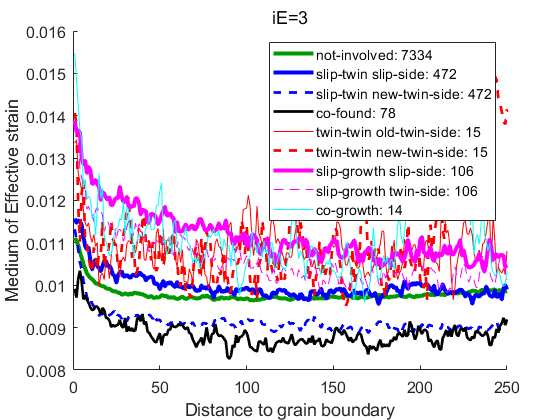

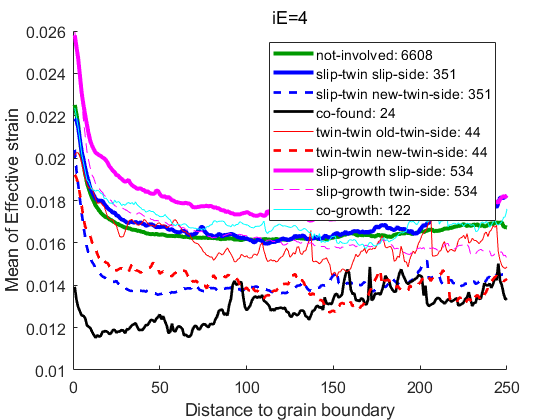

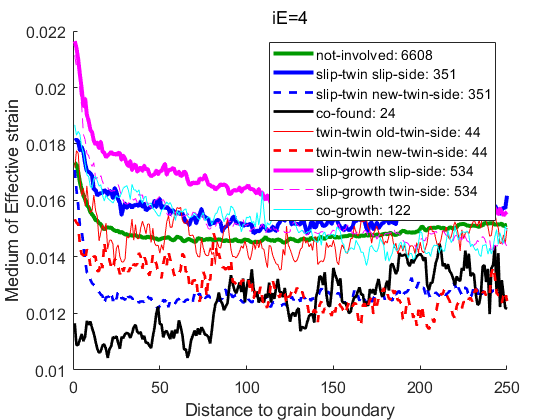

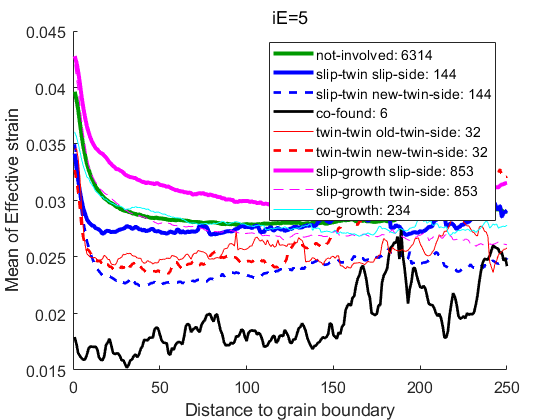

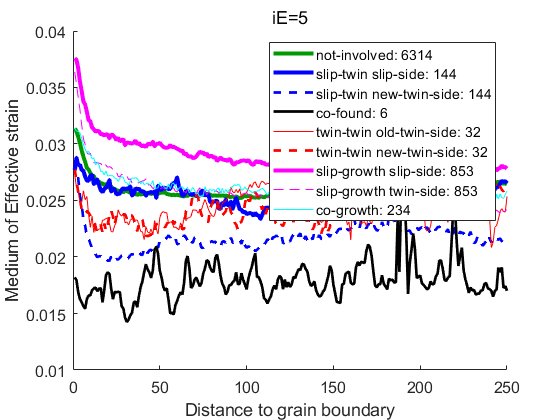

for iE = 2:5
    load(['D:\p\m\DIC_Analysis\temp_results\quants_wrt_gb_',num2str(iE),'.mat']);
    load('D:\p\m\DIC_Analysis\temp_results\saved_data.mat', ['edmat_',num2str(iE)]);
    
    expr = ['edmat_',num2str(iE),';'];
    edmat = evalin('base',expr);
    
    % nanmean
    clear eline_not_involved eline_slip_twin_a eline_slip_twin_b eline_co_found eline_twin_twin_a eline_twin_twin_b eline_slip_growth_a eline_slip_growth_b eline_co_growth
    legend_str = [];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_not_involved, 'rows');
    eline_not_involved = nanmean(edmat(ind,4:end),1);
    legend_str{1} = ['not-involved: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_a, 'rows');
    eline_slip_twin_a = nanmean(edmat(ind,4:end),1);
    legend_str{2} = ['slip-twin slip-side: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_b, 'rows');
    eline_slip_twin_b = nanmean(edmat(ind,4:end),1);
    legend_str{3} = ['slip-twin new-twin-side: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_found, 'rows');
    eline_co_found = nanmean(edmat(ind,4:end),1);
    legend_str{4} = ['co-found: ',num2str(sum(ind))];
    try
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_a, 'rows');
        eline_twin_twin_a = nanmean(edmat(ind,4:end),1);
        legend_str{5} = ['twin-twin old-twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_b, 'rows');
        eline_twin_twin_b = nanmean(edmat(ind,4:end),1);
        legend_str{6} = ['twin-twin new-twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_a, 'rows');
        eline_slip_growth_a = nanmean(edmat(ind,4:end),1);
        legend_str{7} = ['slip-growth slip-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_b, 'rows');
        eline_slip_growth_b = nanmean(edmat(ind,4:end),1);
        legend_str{8} = ['slip-growth twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_growth, 'rows');
        eline_co_growth = nanmean(edmat(ind,4:end),1);
        legend_str{9} = ['co-growth: ',num2str(sum(ind))];
    end
    figure;disableDefaultInteractivity(gca); hold on;
    nPts = length(x_dist);    % or 150
    % ndp_to_plot = 150;
    plot(x_dist(1:nPts),eline_not_involved(1:nPts),'-','color',[0 0.6 0],'LineWidth',3);
    plot(x_dist(1:nPts),eline_slip_twin_a(1:nPts),'-b','LineWidth',3);
    plot(x_dist(1:nPts),eline_slip_twin_b(1:nPts),'--b','LineWidth',2);
    
    plot(x_dist(1:nPts),eline_co_found(1:nPts),'-k','LineWidth',2);
    try
        plot(x_dist(1:nPts),eline_twin_twin_a(1:nPts),'-r','LineWidth',.5);
        plot(x_dist(1:nPts),eline_twin_twin_b(1:nPts),'--r','LineWidth',2);
        
        plot(x_dist(1:nPts),eline_slip_growth_a(1:nPts),'-m','LineWidth',3);
        plot(x_dist(1:nPts),eline_slip_growth_b(1:nPts),'--m','LineWidth',.5);
        plot(x_dist(1:nPts),eline_co_growth(1:nPts),'-c','LineWidth',.5);
    end
    % legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
    legend(legend_str);
    set(gca,'fontsize',12);
    xlabel('Distance to grain boundary');
    ylabel('Mean of Effective strain');
    
    title(['iE=',num2str(iE)],'fontweight','normal');
    
    % median
    clear eline_not_involved eline_slip_twin_a eline_slip_twin_b eline_co_found eline_twin_twin_a eline_twin_twin_b eline_slip_growth_a eline_slip_growth_b eline_co_growth
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_not_involved, 'rows');
    eline_not_involved = median(edmat(ind,4:end),1,'omitnan');
    legend_str{1} = ['not-involved: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_a, 'rows');
    eline_slip_twin_a = median(edmat(ind,4:end),1,'omitnan');
    legend_str{2} = ['slip-twin slip-side: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_b, 'rows');
    eline_slip_twin_b = median(edmat(ind,4:end),1,'omitnan');
    legend_str{3} = ['slip-twin new-twin-side: ',num2str(sum(ind))];
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_found, 'rows');
    eline_co_found = median(edmat(ind,4:end),1,'omitnan');
    legend_str{4} = ['co-found: ',num2str(sum(ind))];
    try
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_a, 'rows');
        eline_twin_twin_a = median(edmat(ind,4:end),1,'omitnan');
        legend_str{5} = ['twin-twin old-twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_b, 'rows');
        eline_twin_twin_b = median(edmat(ind,4:end),1,'omitnan');
        legend_str{6} = ['twin-twin new-twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_a, 'rows');
        eline_slip_growth_a = median(edmat(ind,4:end),1,'omitnan');
        legend_str{7} = ['slip-growth slip-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_b, 'rows');
        eline_slip_growth_b = median(edmat(ind,4:end),1,'omitnan');
        legend_str{8} = ['slip-growth twin-side: ',num2str(sum(ind))];
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_growth, 'rows');
        eline_co_growth = median(edmat(ind,4:end),1,'omitnan');
        legend_str{9} = ['co-growth: ',num2str(sum(ind))];
    end
    
    figure;disableDefaultInteractivity(gca); hold on;
    nPts = length(x_dist);    % or 150
    % ndp_to_plot = 150;
    plot(x_dist(1:nPts),eline_not_involved(1:nPts),'-','color',[0 0.6 0],'LineWidth',3);
    plot(x_dist(1:nPts),eline_slip_twin_a(1:nPts),'-b','LineWidth',3);
    plot(x_dist(1:nPts),eline_slip_twin_b(1:nPts),'--b','LineWidth',2);
    
    plot(x_dist(1:nPts),eline_co_found(1:nPts),'-k','LineWidth',2);
    try
        plot(x_dist(1:nPts),eline_twin_twin_a(1:nPts),'-r','LineWidth',.5);
        plot(x_dist(1:nPts),eline_twin_twin_b(1:nPts),'--r','LineWidth',2);
        
        plot(x_dist(1:nPts),eline_slip_growth_a(1:nPts),'-m','LineWidth',3);
        plot(x_dist(1:nPts),eline_slip_growth_b(1:nPts),'--m','LineWidth',.5);
        plot(x_dist(1:nPts),eline_co_growth(1:nPts),'-c','LineWidth',.5);
    end
    % legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
    legend(legend_str);
    set(gca,'fontsize',12);
    xlabel('Distance to grain boundary');
    ylabel('Medium of Effective strain');
    
    title(['iE=',num2str(iE)],'fontweight','normal');
end